x_0 = 0;
x_dot_0 = 0;
x_ddot_0 = 0;

x_des = 6;
x_dot_des = 0;
x_ddot_des = 0;

t_0 = 0;
t_end = 25;

waypoints = [x_0    x_dot_0     x_ddot_0;
             x_des  x_dot_des   x_ddot_des;
             x_des  x_dot_des   x_ddot_des]';
time = [t_0 t_end 50];

t = time;
time_size = size(t);
point = (size(t) - 1) * 100;
%T = linspace(0, time_size(2) - 1, point(2));
T = linspace(0, time(end), point(2));
p = zeros(point(2), 1);
v = zeros(point(2), 1);
a = zeros(point(2), 1);

for n = 0 : time_size(2) - 2

    border_conditions_sigm = reshape(waypoints(:, n + 1 : n + 2),1,[]);
    %disp(border_conditions_sigm)

    coefficients = zeros(6, 1);

    parameters = [1 * (t(n + 1) ^ 5), 1 * (t(n + 1) ^ 4), 1 * (t(n + 1) ^ 3), 1 * (t(n + 1) ^ 2), 1 * (t(n + 1) ^ 1), 1 * (t(n + 1) ^ 0);
                  5 * (t(n + 1) ^ 4), 4 * (t(n + 1) ^ 3), 3 * (t(n + 1) ^ 2), 2 * (t(n + 1) ^ 1), 1 * (t(n + 1) ^ 0), 0 * (t(n + 1) ^ 0);
                  20 * (t(n + 1) ^ 3), 12 * (t(n + 1) ^ 2), 6 * (t(n + 1) ^ 1), 2 * (t(n + 1) ^ 0), 0 * (t(n + 1) ^ 0), 0 * (t(n + 1) ^ 0);
                  1 * (t(n + 2) ^ 5), 1 * (t(n + 2) ^ 4), 1 * (t(n + 2) ^ 3), 1 * (t(n + 2) ^ 2), 1 * (t(n + 2) ^ 1), 1 * (t(n + 2) ^ 0);
                  5 * (t(n + 2) ^ 4), 4 * (t(n + 2) ^ 3), 3 * (t(n + 2) ^ 2), 2 * (t(n + 2) ^ 1), 1 * (t(n + 2) ^ 0), 0 * (t(n + 2) ^ 0);
                  20 * (t(n + 2) ^ 3), 12 * (t(n + 2) ^ 2), 6 * (t(n + 2) ^ 1), 2 * (t(n + 2) ^ 0), 0 * (t(n + 2) ^ 0), 0 * (t(n + 2) ^ 0)];

    coefficients = inv(parameters) * border_conditions_sigm';

    power_size = size(coefficients) - 1;
    power = power_size(1);

    for pow = 0 : power
        %disp(pow)
        p(n * 100 + 1 : (n + 1) * 100) = p(n * 100 + 1 : (n + 1) * 100) + (coefficients(power - pow + 1) .* (T(n * 100 + 1 : (n + 1) * 100) .^ pow)');
        %disp(coefficients(power - pow + 1))
        %disp(T(n * 10 + 1 : (n + 1) * 10) .^ pow)
        %disp(p')

        if pow > 0
            v(n * 100 + 1 : (n + 1) * 100) = v(n * 100 + 1 : (n + 1) * 100) + (pow * coefficients(power - pow + 1) .* (T(n * 100 + 1 : (n + 1) * 100) .^ (pow - 1))');
            %disp(v(n * 10 + 1 : (n + 1) * 10)')
            %disp(pow * coefficients(power - pow + 1)')
            %disp(T(n * 10 + 1 : (n + 1) * 10) .^ pow - 1)
        end

        if pow > 1
            a(n * 100 + 1 : (n + 1) * 100) = a(n * 100 + 1 : (n + 1) * 100) + (pow * (pow - 1) * coefficients(power - pow + 1) .* (T(n * 100 + 1 : (n + 1) * 100) .^ (pow - 2))');
        end
    end
end

desired_state.time = [T'];
desired_state.pos = [p];
desired_state.vel = [v];
desired_state.acc = [a];
desired_state.yaw = zeros(400, 1);
desired_state.yawdot = zeros(400, 1);

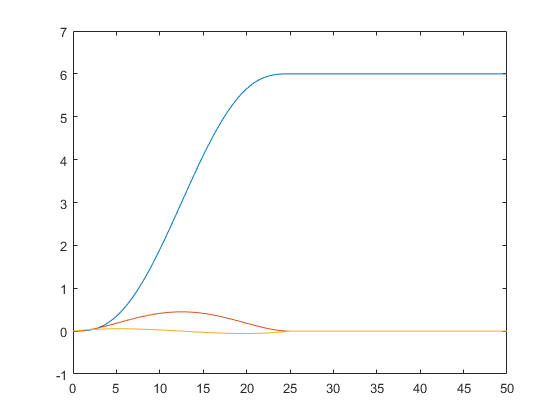

plot(desired_state.time, desired_state.pos)
hold on
plot(desired_state.time, desired_state.vel)
plot(desired_state.time, desired_state.acc)